*    Prev: Main Menu*

# **Modeling the Underwater Vehicle Platform**

*Last updated: April 14th, 2021*

A reasonably accurate dynamic model of the vehicle platform is an essential tool for the development and evaluation of any complex guidance and navigation control algorithms for an autonomous system. In addition, a good model will give us the ability to test and verify system-level and component-level requirements using desktop simulation, and allow us to find and fix errors early in the design process, which will result in significantly reduced risks and fewer issues when moving either to prototypes or production hardware.

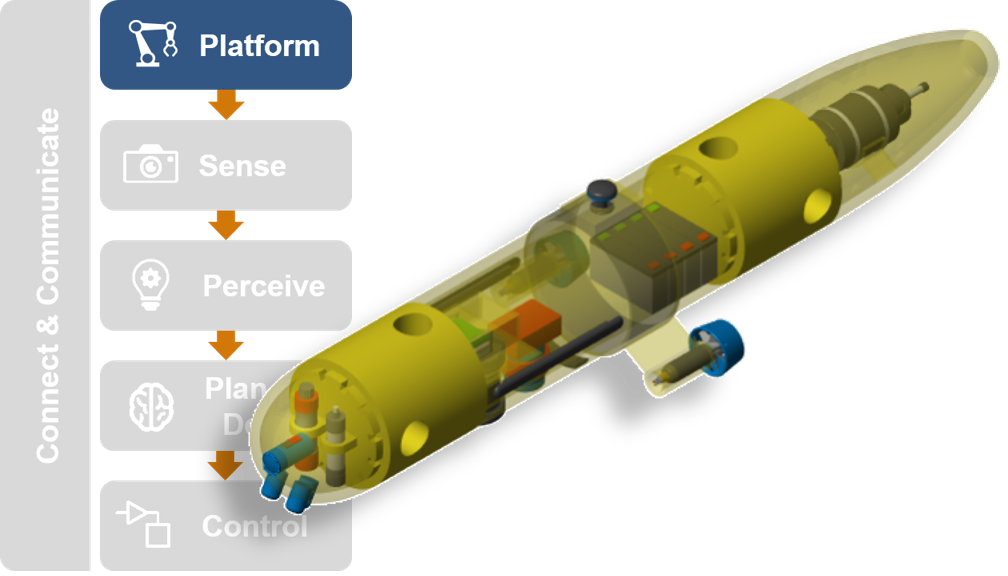

This section presents an overview of some of the basic capabilities in [Simscape](matlab:web(fullfile(docroot, 'physmod/simscape/index.html'))) for modeling and simulation of multi-domain physical systems. In particular, the oulined workflow focuses on [Simscape Multibody](matlab:web(fullfile(docroot, 'physmod/sm/index.html'))) for modeling the mechanical dynamics, and its integration with Simscape and [Simscape Electrical](matlab:web(fullfile(docroot, 'physmod/sps/index.html'))) for modeling the propulsion actuators as well as the electric power distribution system of the autonomous underwater vehicle platform.

## Underwater Vehicle Dynamics

An appropriate dynamic model for a fully autonomous underwater vehicle platform needs to include the motion of the vehicle in six degrees of freedom, gravitational and buoyancy effects, hydrodynamic drag and lift forces generated by the vehicle body moving in water, added mass effects induced by the accelerations of the water displaced by the vehicle, disturbance forces from underwater currents, and the propulsive forces from the main propellers and tunnel thrusters.

The model will conform to a North-East-Down (NED) inertial frame of reference convention, and align a non-inertial body frame, attached to the center of mass of the vehicle, with the surge (longitudinal), sway (lateral) and heave (vertical) principal axes of the vehicle body.

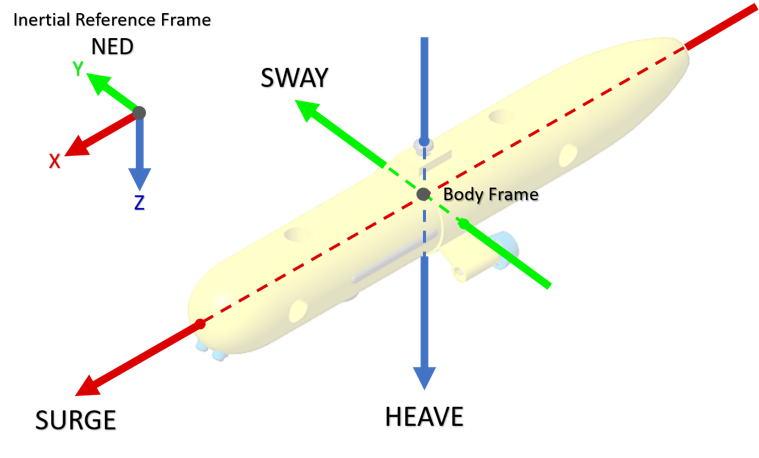

We will develop the mathematical model of the vehicle in Simulink using Simscape Multibody, which provides a specialized environment for modeling and simulating complex 3D mechanical systems.

At its core, Simscape Multibody treats any mechanism as a combination of interconnected bodies (inertias), joints and constraints (relative DoFs), and force elements, and uses that approach to formulate and solve the dynamics for the complete system without the user having the need to explicitly derive any equations of motion.

### Fundamental mechanical modeling techniques

To get started with a new mechanism, open the pre-made template for a new Simscape Multibody model. This pre-made template is located under the Simscape section on the [Simulink Start Page](matlab:simulink).

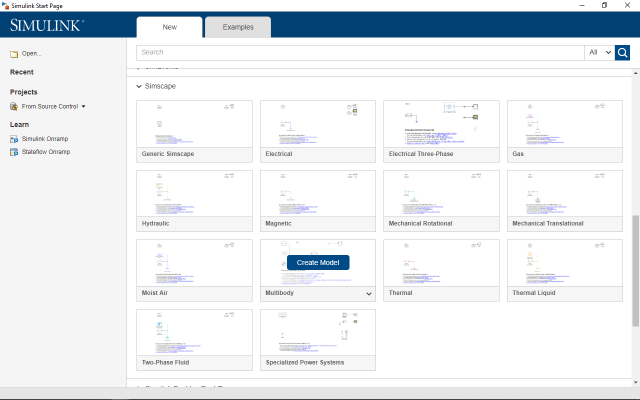

smnew;

#### Create mechanical models using rigid body primitives

The [Body Elements](matlab:open_system('sm_lib','loadonly');open_system('sm_lib/Body Elements')) block library provides a variety of preset shapes like bricks, cylinders, extrusions, etc. Custom shapes can also be imported from external files in STEP or STL format. Body frames can be rigidly connected using [Rigid Transform](matlab:web(fullfile(docroot, 'physmod/sm/ref/rigidtransform.html?container=jshelpbrowser'))) blocks to form compound rigid bodies.

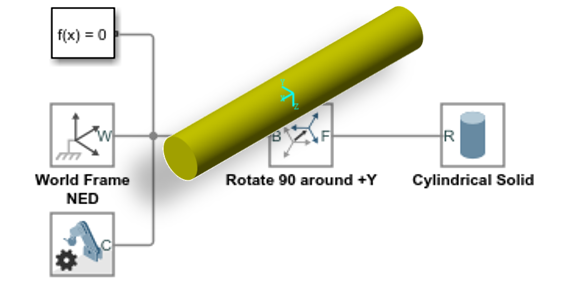

Rigid Transform blocks can also be used to create arbitrary frame rotations and translations to align bodies with the World frame or relative to each other, and to line up frames with the appropriate degrees of freedom.

open_system('AUV_MechanicsStartNew');

#### Explore parameterized designs

An important advantage of being able to use rigid body primitives, especially in the initial exploratory stages of the design - when CAD drawings of the mechanical parts might not yet be available - is that these parts can be fully parameterized using MATLAB variables and expressions.

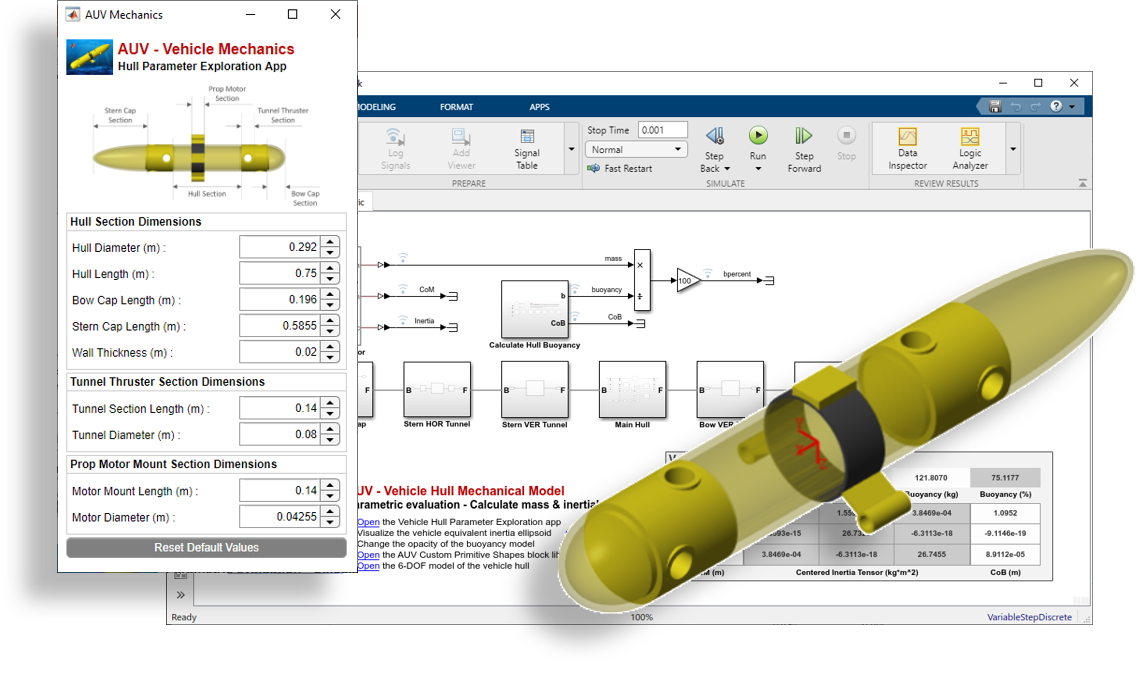

This means you can use simple MATLAB scripts or create customized graphical user interfaces with the MATLAB [App Designer](matlab:web(fullfile(docroot, 'matlab/ref/appdesigner.html'))) to modify any parameters in the mechanical model and quickly evaluate the effect of those parameter changes in the preliminary design.

open_system('AUV_MechanicsHullParametric');

#### Model joint connections and external forces and torques

[Joint](matlab:web(fullfile(docroot, 'physmod/sm/ug/joints.html'))) blocks connect the frames of two rigid bodies and impose the primary kinematic constraints that determine how these bodies can move relative to each other. Joint blocks are parameterized in terms of the Degrees of Freedom they provide. These DoFs range from zero in the [Weld Joint](matlab:web(fullfile(docroot, 'physmod/sm/ref/weldjoint.html?container=jshelpbrowser'))) block to six - three translational and three rotational - in the [6-DOF Joint](matlab:web(fullfile(docroot, 'physmod/sm/ref/6dofjoint.html?container=jshelpbrowser'))) and [Bushing Joint](matlab:web(fullfile(docroot, 'physmod/sm/ref/bushingjoint.html?container=jshelpbrowser'))) blocks. All joints provide the means for actuating (with either forces and/or torques or motion profiles) and sensing their corresponding DoFs.

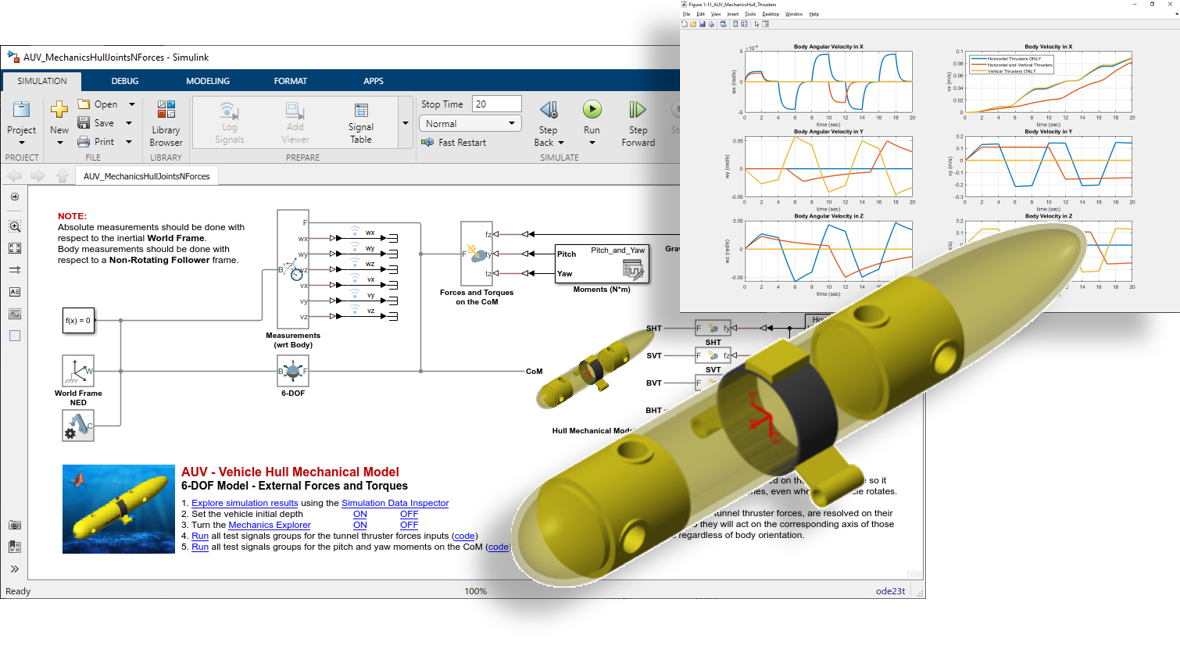

The [External Force and Torque](matlab:web(fullfile(docroot, 'physmod/sm/ref/externalforceandtorque.html'))) block can be used to apply forces and/or torques to a connected rigid body frame. The block provides options to select the resolution frame - World or attached frame - for the exertion of each external force and torque.

The [Transform Sensor](matlab:web(fullfile(docroot, 'physmod/sm/ref/transformsensor.html'))) block provides measurements of the spatial relationship between any two frames in the multibody model. These measurements are resolved with respect to a chosen measurement frame - measurement resolution options include World as well as rotating and non-rotating base and follower frames.

open_system('AUV_MechanicsHullJointsNForces');

#### Create mechanical models using part files from CAD

The [File Solid](matlab:web(fullfile(docroot, 'physmod/sm/ref/filesolid.html?container=jshelpbrowser'))) block associates individual part files from most standard CAD formats to body blocks in the Simscape Multibody model. Geometry and material properties are read directly from the part file or can be customized on the block mask.

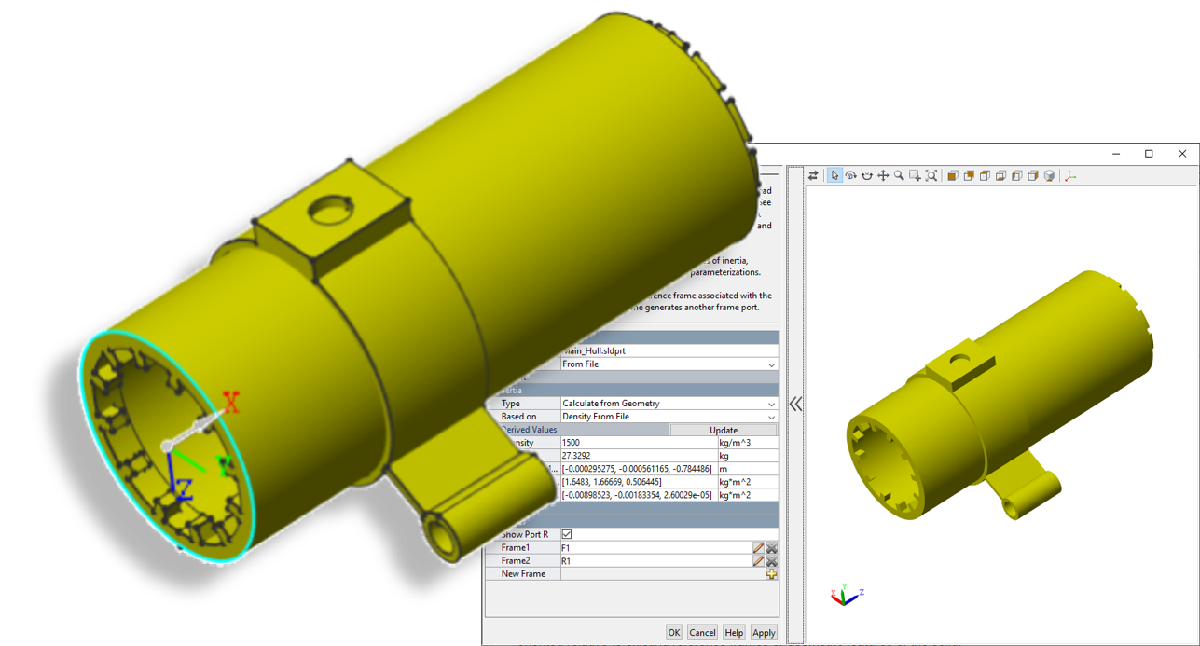

New body frames can be defined on the 3D interface and added to the part. The new frames can be positioned and oriented relative to existing reference frames or geometric features of the solid.

open_system('AUV_MechanicsStartNewCAD');

#### Add tracking cameras in the Mechanics Explorer

Cameras define the model viewpoints used during animation playback. The [Mechanics Explorer](matlab:web(fullfile(docroot, 'physmod/sm/ref/mechanicsexplorer-app.html'))) supports two camera types - global and dynamic. The global camera provides a static viewpoint that you can manipulate interactively during animation and playback. Dynamic cameras can be attached to any frame in the model, and provide moving viewpoints that can be predefined using the [Camera Manager](matlab:web(fullfile(docroot, 'physmod/sm/ref/cameramanager-app.html'))) and enable the tracking of any moving part in the system.

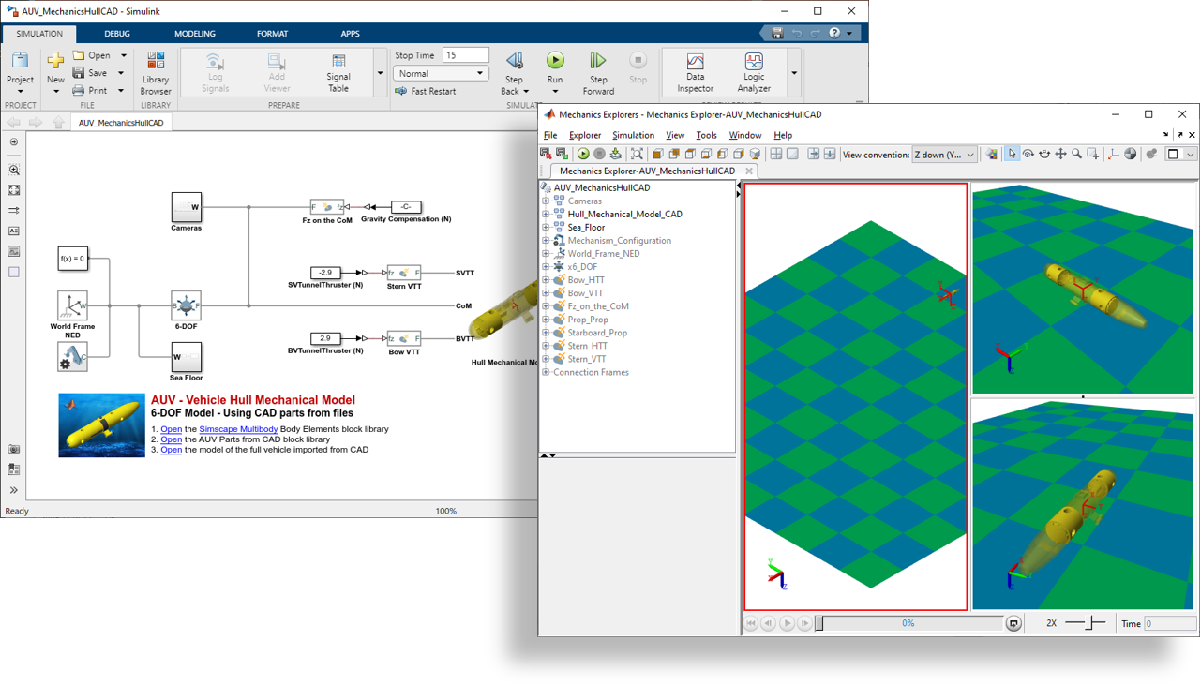

open_system('AUV_MechanicsHullCAD.slx');

### Import complete mechanical assemblies from CAD

Full mechanical assemblies, including all masses, inertias, mates, and 3D geometry can be translated directly from multiple CAD packages (including SolidWorks®, PTC® Creo and Autodesk Inventor®) and automatically imported into a model using the [Simscape Multibody Link](matlab:web(fullfile(docroot, 'physmod/smlink/ug/installing-and-linking-simmechanics-link-software.html'))) CAD plug-in. This plug-in can be downloaded for free from the [Simscape Multibody Link download page](https://www.mathworks.com/campaigns/offers/download_smlink.html).

[Open](matlab:winopen('AUV.sldasm');) the autonomous underwater vehicle SolidWorks® assembly file, and use the Simscape Multibody Link Export function under the Tools menu. If SolidWorks® is not available, the translation process can be reviewed in this step by step [video](matlab:winopen('AUVCADTranslation.mp4');).

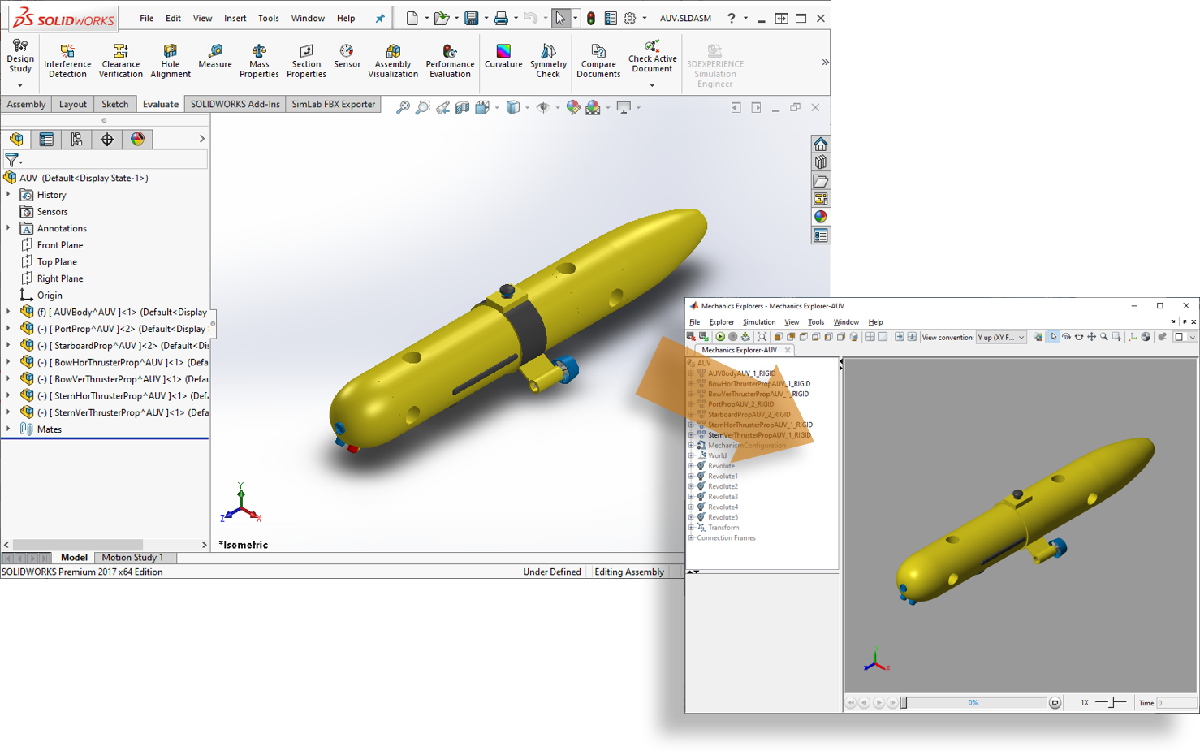

After the CAD translation is finished and the corresponding .xml file is generated, the associated Simscape Multibody model can be automatically created using the [*smimport( )*](matlab:web(fullfile(docroot, 'physmod/sm/ref/smimport.html'))) function.

smimport('AUV.xml')

### Compute inertial properties and hydrostatic forces

The [Inertia Sensor](matlab:web(fullfile(docroot, 'physmod/sm/ref/inertiasensor.html'))) block provides the means to measure the inertial properties - mass, center of mass, inertia tensors -  for individual or collections of body elements in a Simscape Multibody model.

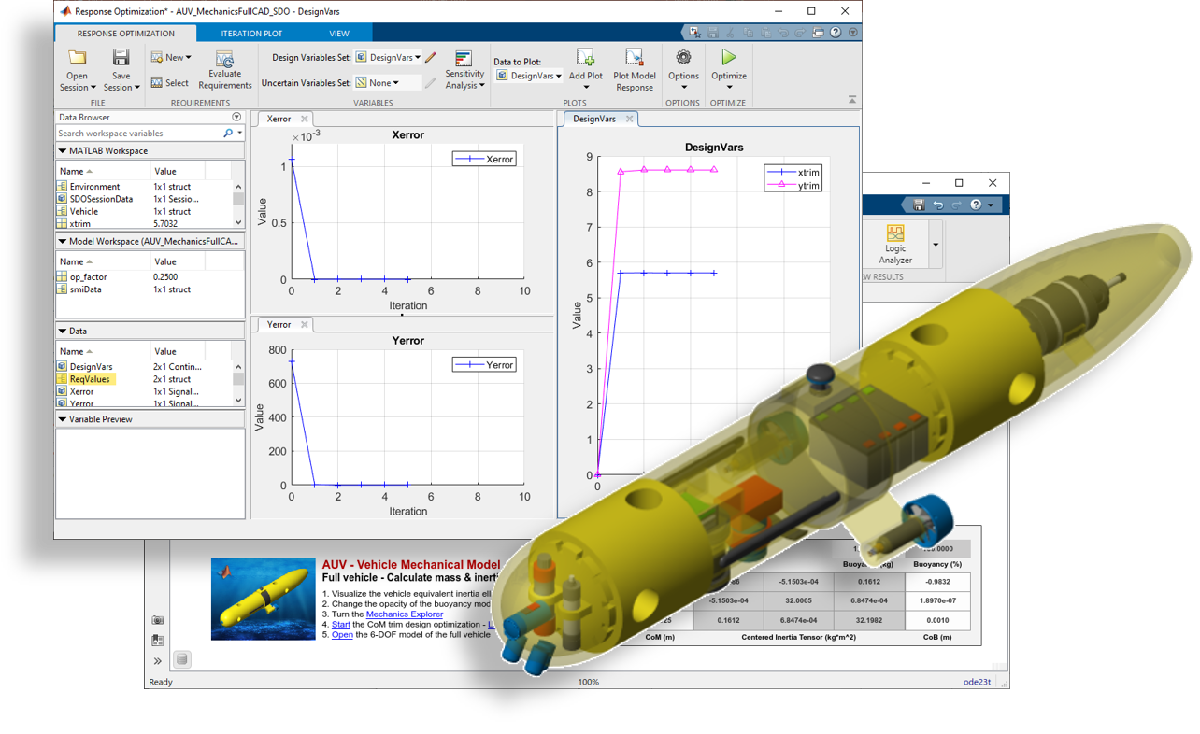

Once the complete mechanical model of the vehicle - including all mass and inertial contributions from sensors and electronic components - has been implemented in Simscape Multibody, we can fine tune the location of the resulting center of mass by performing a design optimization directly on the Simulink model using the [Response Optimization](matlab:web(fullfile(docroot, 'sldo/response-optimization.html'))) App.

open_system('AUV_MechanicsFullCAD_SDO');

### Apply hydrostatic forces - gravity and buoyancy effects

In order to maintain stable equilibrium, a fully submerged underwater vehicle must have the center of gravity situated directly below the center of buoyancy. This will generate a restoring moment that counters any external forces or disturbances that produce rotations around the body roll and/or pitch axes and will help bring the vehicle back to a leveled orientation.

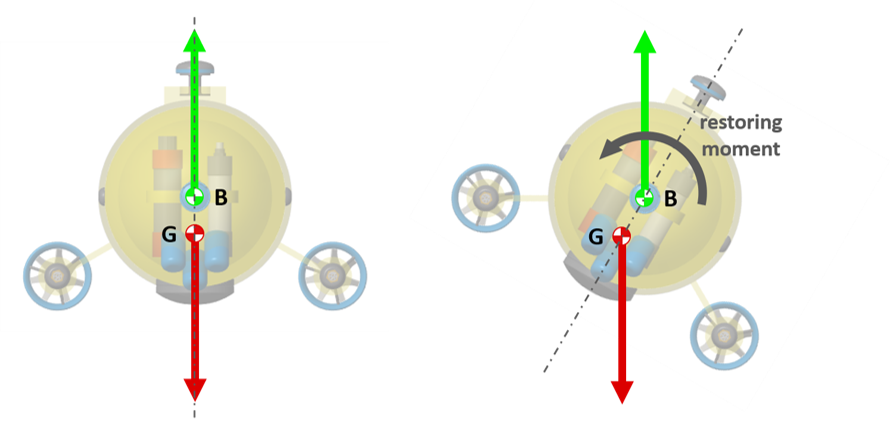

Note that both the gravitational force and the buoyancy force are always aligned with the vertical axis of the world reference frame, and the restoring moment will always act to bring back the center of gravity to its original position below the center of buoyancy.

open_system('AUV_MechanicsFullHydrostatics');

### Apply hydrodynamic forces - drag, lift, and added mass effects

The fundamental governing equation for the dynamics of the underwater vehicle is of the form:


$$\left(M_{RB} +M_A \right)\dot{\nu} +\left({C_{RB} \left(\nu \right)+C}_A \left(\nu \right)\right)\nu +D\left(\nu \right)\nu +g\left(\eta \right)=F_{propulsion}$$


Where $\nu ={\left\lbrack \begin{array}{cc}
V_b  & \omega_b 
\end{array}\right\rbrack }^T ={\left\lbrack \begin{array}{cccccc}
u & v & w & p & q & r
\end{array}\right\rbrack }^T$ is the body-fixed velocity vector, $\eta ={\left\lbrack \begin{array}{cccccc}
x & y & z & \phi  & \theta  & \psi 
\end{array}\right\rbrack }^T$ is the earth-fixed position and orientation vector, $M_{\textrm{RB}}$ and $C_{\textrm{RB}} \left(\nu \right)$are the mass matrix and coriolis effects associated with the rigid body, $M_A$ is the added mass matrix, $C_A \left(\nu \right)$is the coriolis effect induced by the added mass, $D\left(\nu \right)$ is the damping matrix that includes all the drag and lift forces, and $g\left(\eta \right)$ represents the combined gravitational and buoyancy effects. Note that Simscape Multibody will take care of implementing the rigid body dynamics as well as account for the gravitational forces. All other effects will need to be applied as external forces and moments.

**Drag and lift forces** are the result of pressure and friction due to fluid flowing around the surface of the vehicle. Lift is perpendicular to the flow direction and drag is parallel and opposite the flow direction. Both of these forces are a function of the square of the velocity, and are highly dependent on the shape of the vehicle, the transitions between laminar and turbulent regimes in the flow defined by the Reynolds number, the skin friction, the distance to the ocean bottom, and specifically the incidence angle $\alpha$ (the inclination of the body with respect to direction of the flow) and the side slip angle $\beta$ (the lateral deviation from the glide path) among many other complex factors.

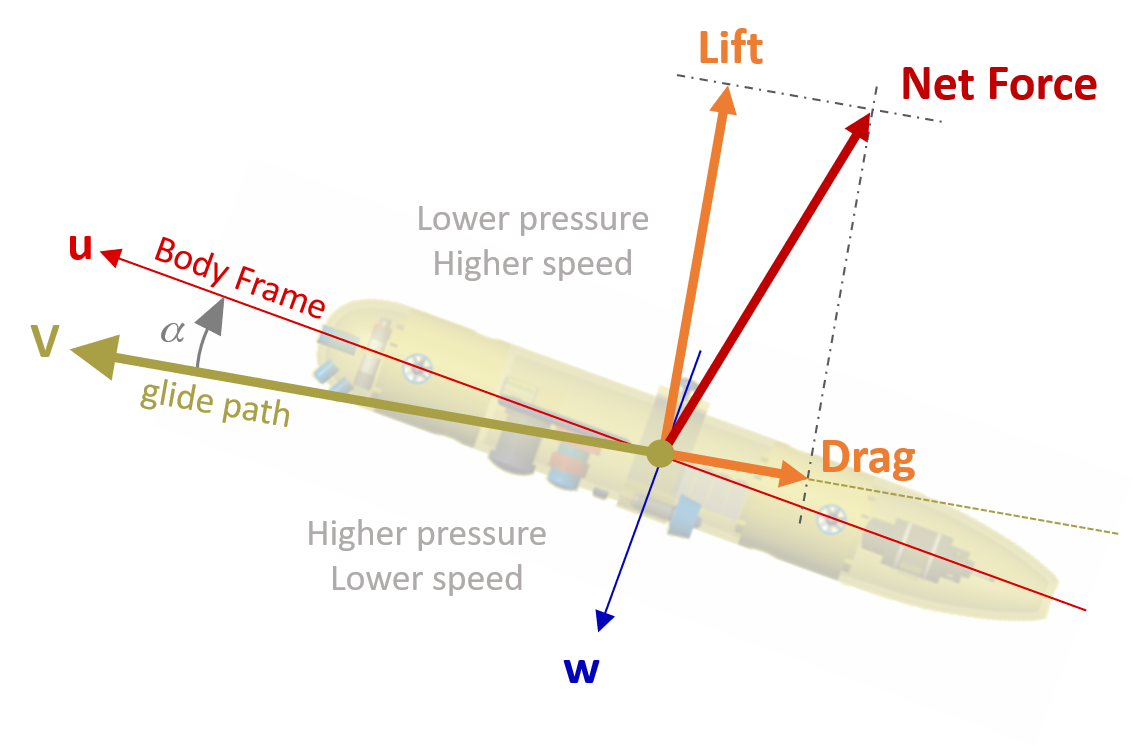

        
$$F_{drag} = \frac{1}2\rho V^2C_dA\;\;\;\;\;\;\;\;F_{lift} = \frac{1}2\rho V^2C_lA$$


Where $\rho$ is the density of the fluid, $V$is the vehicle velocity and $A$ is a cross section reference area. Drag and lift coefficients $C_d$ and $C_l$ are normally obtained from laboratory experiments and used in practice to capture and characterize the many additional complex dependencies between the fluid and the surface of the vehicle.

**Added mass** is a pressure induced force and moment on the body resulting from the inertial characteristics of the volume of surrounding fluid that must be moved as the vehicle accelerates or decelerates. This effect is significant for bodies moving in water, and its contribution can be modeled as an apparent increase in the actual mass of the underwater vehicle.

In general, computing the added mass matrix coefficients for a generic shape, is a complex problem that needs to be solved using CFD methods and validated experimentally. However, there exist several simplified methods that  provide appropriate first order approximations for commonly used shapes (i.e. spheres, cylinders, plates, etc.)

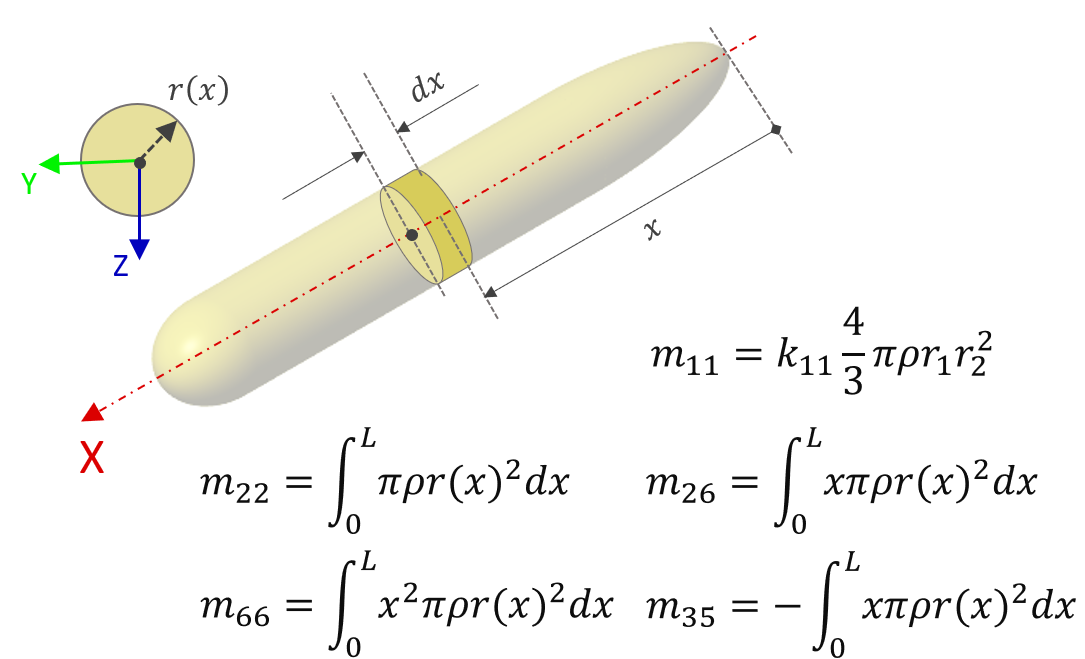     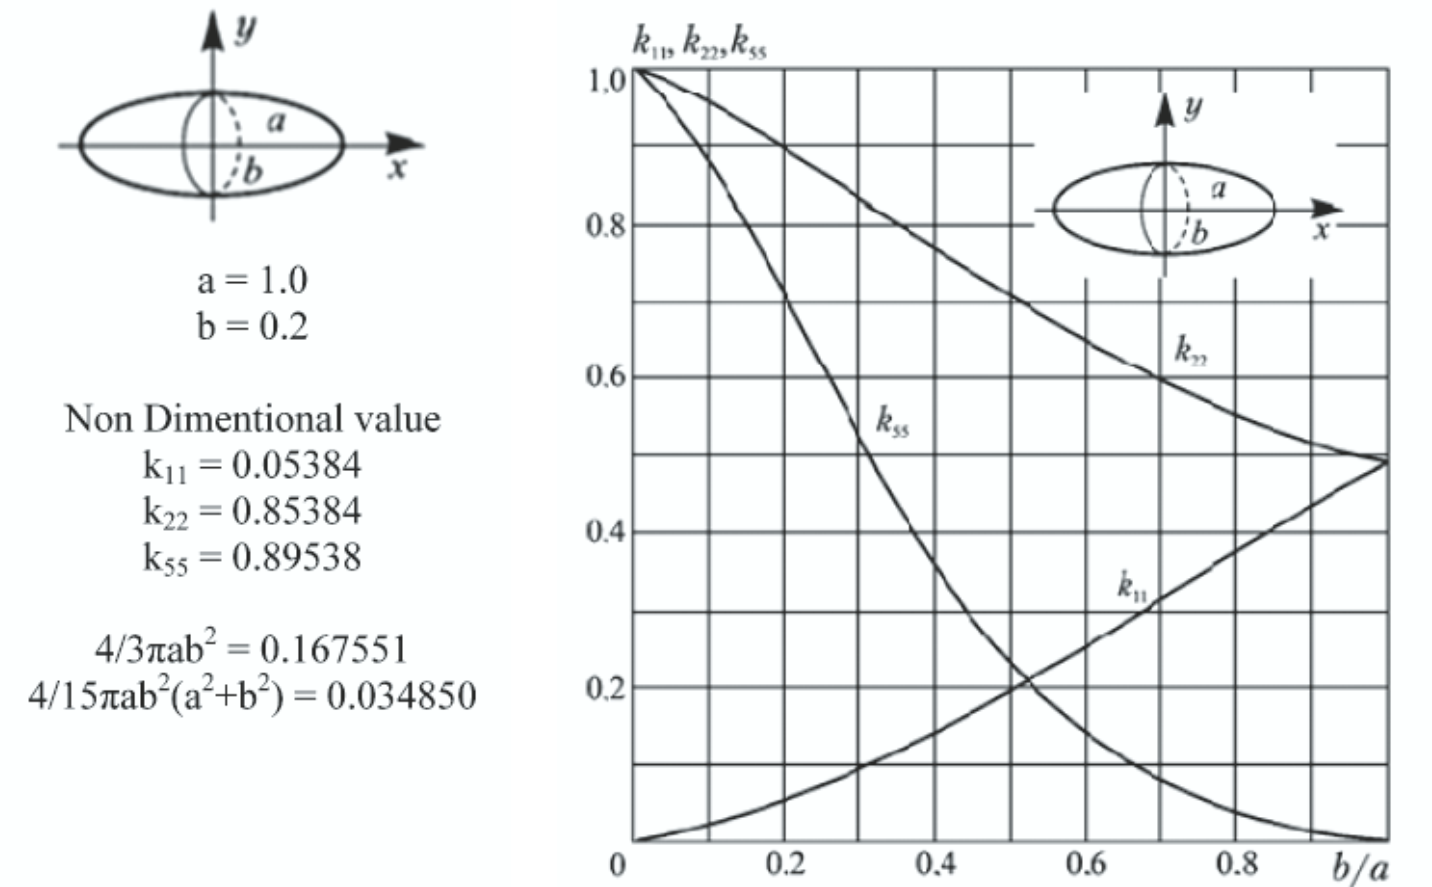

For our [example](matlab:edit('calc_addedmassMatrix')), the hull of the vehicle is a typical elongated myring shape, so we will assume rotational symmetry around the x-axis and apply a combination of **slender body** theory and **Lamb's k-factors** for a prolate spheroid to estimate the coefficients of the added mass matrix, which will then be reduced to the form:


$$M_A =\left\lbrack \begin{array}{cccccc}
m_{11}  & 0 & 0 & 0 & 0 & 0\\
0 & m_{22}  & 0 & 0 & 0 & m_{26} \\
0 & 0 & m_{33}  & 0 & m_{35}  & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & m_{53}  & 0 & m_{55}  & 0\\
0 & m_{62}  & 0 & 0 & 0 & m_{66} 
\end{array}\right\rbrack$$
    

For underwater vehicles these coefficients are usually taken as constants and given the assumption of top-down and port-starboard symmetry, we can also make: $m_{22} = m_{33}$ and $m_{55} = m_{66}$.

open_system('AUV_MechanicsFullHydrodynamics');

### Compare and contrast mechanical modeling implementations

[Subsystem Variants](matlab:web(fullfile(docroot, 'simulink/slref/variantsubsystemvariantmodel.html'))) in Simulink provide an efficient way to include different implementations for individual parts of a single model. Only one of these implementations can be active at a time, and the choice of the active variant, or the active combination of variants, can be easily controlled with a MATLAB parameter or expression.

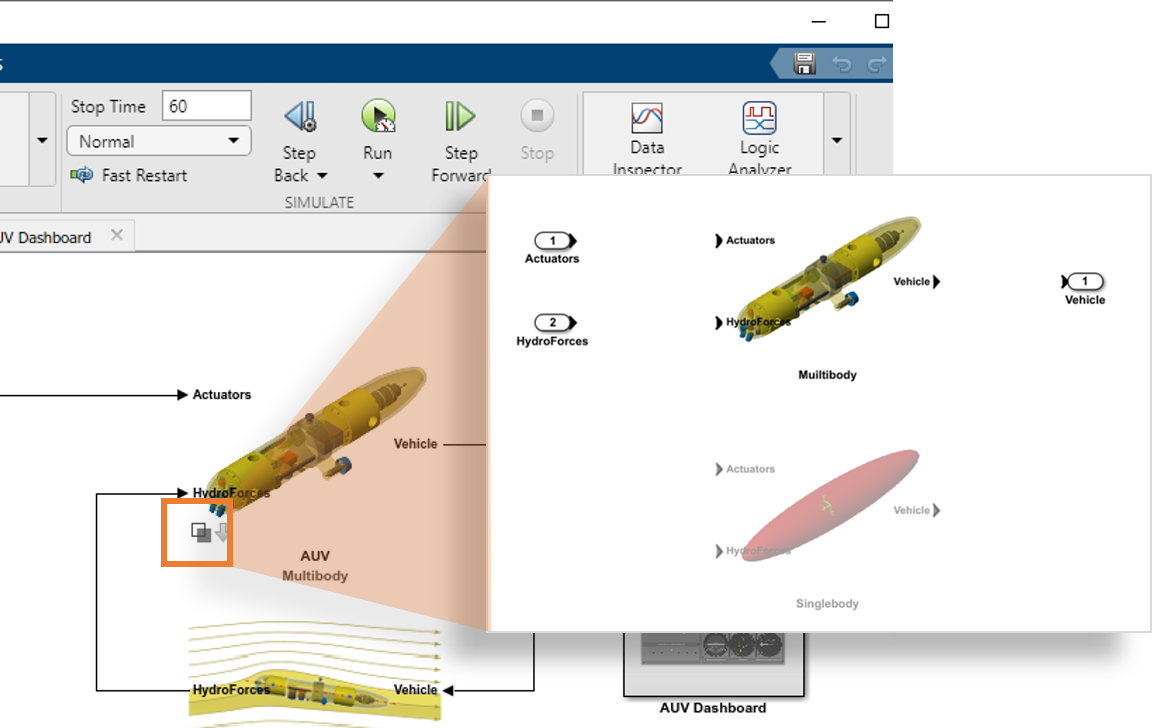

We will leverage the single body [6DOF (Euler Angles)](matlab:web(fullfile(docroot, 'aeroblks/6dofeulerangles.html'))) block from the Equations of Motion library in the [Aerospace Blockset](matlab:web(fullfile(docroot, 'aeroblks/index.html'))) to provide an alternative to our multibody representation of the underwater vehicle rigid body dynamics. This will allow us to compare and contrast both implementations against each other and give us the flexibility to choose the more appropriate variant to use for a given simulation task.

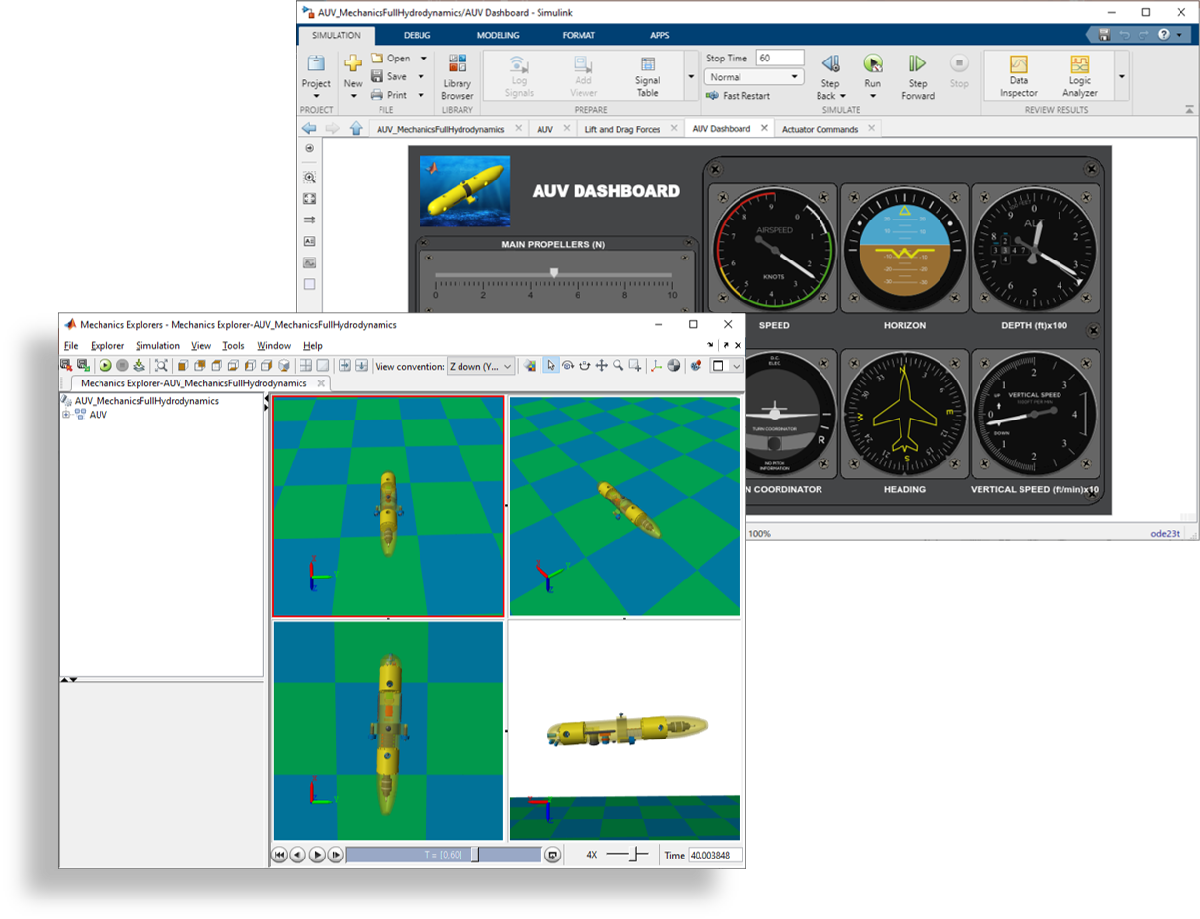

In addition, we can take advantage of the collection of standard cockpit dashboard displays included in the [Flight Instruments](matlab:web(fullfile(docroot, 'aeroblks/flight-instruments.html'))) library of the Aerospace Blockset. Even though the use of these displays is aimed at more traditional aircraft applications, they can be adapted to monitor the status of our underwater vehicle during simulation.

open_system('AUV_MechanicsFullHydrodynamicsVAR');

## Underwater Vehicle Electrical Distribution and Propulsion

Battery life and total power consumption are crucial factors on the endurance and mission capabilities for an autonomous underwater vehicle. Incorporating the dynamics of the battery, the electric motors, and the distribution of power to the on-board sensors, electronics, and communication devices into our system-level model will enable us to simulate the complete vehicle platform, and help us avoid possible integration issues later in the design process.

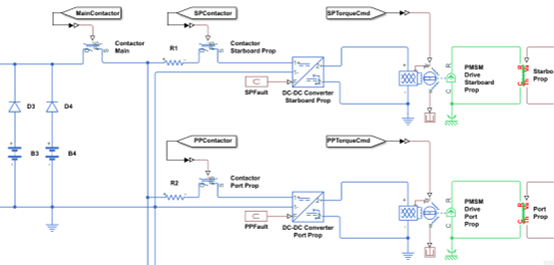

For this task, we will use Simscape and Simscape Electrical. These libraries provide components that can be assembled into schematic diagrams and allow rapid model creation of electro-mechanical systems that directly integrate with block diagrams and other modeling constructs in the Simulink environment.

### Electrical circuit modeling basics

To get started with a new electrical circuit, open the pre-made template for a new Simscape Electrical model. This pre-made template is located under the Simscape section on the [Simulink Start Page](matlab:simulink).

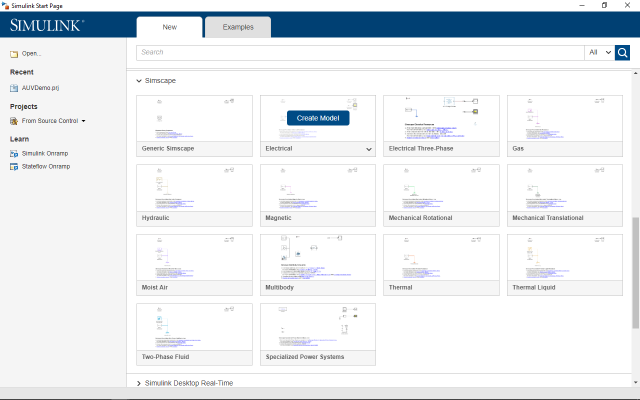

ssc_new('','electrical');

#### Model generic electrical actuators

A motor is a general purpose electro-mechanical actuation device that converts electrical energy into rotational mechanical energy - producing a torque that is proportional to its armature current and a corresponding voltage drop proportional to its angular velocity.

The equivalent electrical circuit for a simple DC motor is represented by an armature resistor and an armature inductor connected in series. The equivalent mechanical circuit is represented by a rotor inertia and usually, some internal rotor damping. These dynamics can be represented by two first order differential equations:

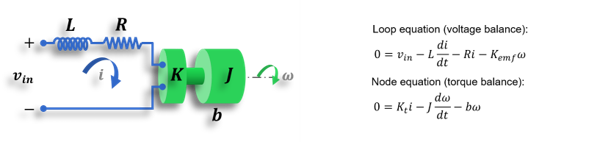

open_system('AUV_ElectricalDCmotorFoundation');

#### Model simplified electric motor drives

The [Simplified PMSM Drive](matlab:web(fullfile(docroot, 'physmod/sps/ref/simplifiedpmsmdrive.html?container=jshelpbrowser'))) block represents a brushless dc motor model with closed-loop torque control. This block abstracts the torque-speed behavior of the combined motor and motor driver in order to support system-level simulation where simulation speed is important.

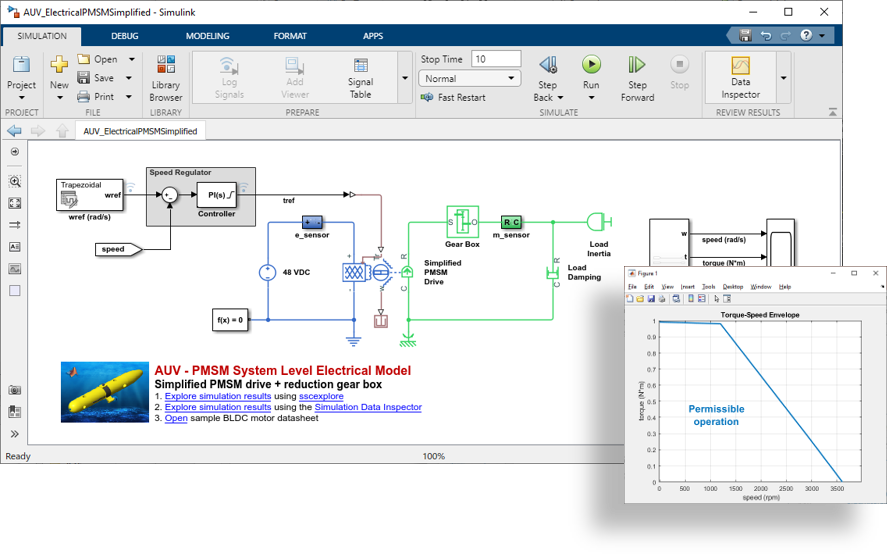

Note that the [Electromechanical](matlab:open_system('ee_lib','loadonly');open_system('ee_lib/Electromechanical')) libraries in Simscape Electrical contain a number of pre-made component models for a variety of motor types: from generic linear and rotary actuators, to induction machines, to stepper motors, to brushless dc and permanent magnet synchronous motors.

A variety of application examples for all these different motor types can be found in the documentation. For a more detailed example model of a speed controller for a BLDC motor drive, including the commutation logic and the transistor gate controls for a three-phase IGBT inverter, refer to [this](matlab:web(fullfile(docroot, 'physmod/sps/ug/bldc-speed-control.html'))) documentation page.

open_system('AUV_ElectricalPMSMSimplified');

#### Create custom components

With the MATLAB based [Simscape language](matlab:web(fullfile(docroot, 'physmod/simscape/lang/what-is-the-simscape-language.html'))) you can create custom physical components, domains and libraries. Custom Simscape language files (.ssc) can be included in a model diagram by using the [Simscape Component](matlab:web(fullfile(docroot, 'physmod/simscape/ref/simscapecomponent.html?container=jshelpbrowser'))) block, or alternatively, the command [*ssc_build*](matlab:web(fullfile(docroot, 'physmod/simscape/ref/ssc_build.html'))) automatically creates a Simscape library file containing the sublibraries and blocks generated from all the Simscape files in a specified package directory.

The Simscape language supports a variety of constructs and a large number of functions and allows the user to define the desired mathematical relationships between the component variables.

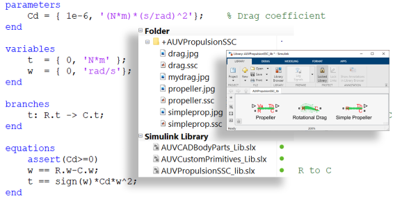

As an example, we slightly modified the code of the original Foundation Library [Rotational Damper](matlab:web(fullfile(docroot, 'physmod/simscape/ref/rotationaldamper.html'))) to implement a custom Rotational Drag component.

open_system('AUV_ElectricalCustomDrag');

### Model propellers and thrusters

The thrust and torque characteristics of the propellers and thrusters will have significant influence in the performance of the underwater vehicle. It is critical that these characteristics be properly represented in any dynamic simulation model of the platform.

Thrust and torque have complex nonlinear relationships that are highly dependent on the propeller geometry - diameter, pitch or advance ratio, blade area, blade thickness, etc. - number of blades, rotational speed, inflow velocity of the fluid and Reynolds number among many other factors. To avoid this complexity, we will take advantage of commonly used propeller efficiency curves ([Wageningen B-series Propellers](matlab:open('PropellerEfficiencyCurves.pdf'))) to extract the values of the thrust and torque coefficients $K_t$ and $K_q$, as well as the open water efficiency $\eta_o$ for our calculations.

For a given number of blades and a given expanded area ratio - i.e. the ratio of the blade area outside of the hub with respect to the overall propeller disk area - the charts provide the values for these coefficients as a function of the pitch to diameter ratio and the advance velocity coefficient $J = V_a/ND$.

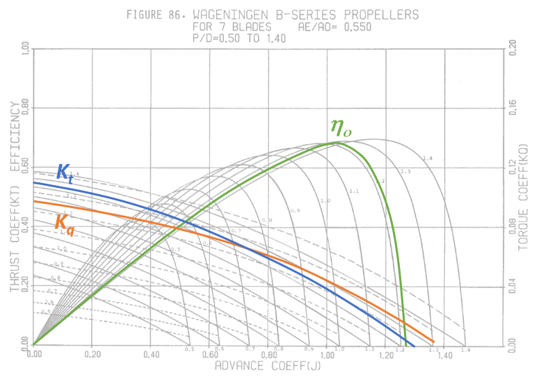

           
$$T = K_t\rho N^2 D^4 \;\;\;\;\;\;\;\;Q = K_q \rho N^2 D^5 $$


Where $T$ is the propeller axial thrust force and $Q$ is the propeller shaft torque, $\rho$ is the density of the fluid, $N$ is the propeller rotational speed in rev/sec and $D$ is the propeller diameter.

open_system('AUV_ElectroMechanicsSSCPropeller');

### Interface with the 3D mechanical model

In order to directly connect the electric motor and the propeller dynamics into the 6-DoF vehicle model, it is necessary to create an interface between the Simscape 1-D Rotational Mechanics domain and the 3-D Revolute Joint in Simscape Multibody using physical signals.  

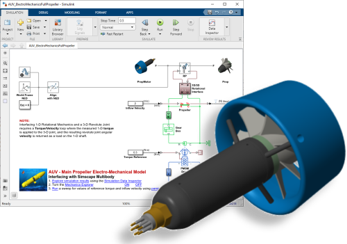

This rotational interface requires a Torque/Velocity loop where the measured 1-D torque is applied to the 3-D joint, and the resulting revolute joint angular velocity is returned as a load on the 1-D shaft.

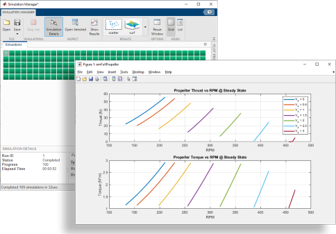

We can use this example model to evaluate the propeller response to a range of reference torque and inflow velocity values at steady state. Note that when running a large number of tests or multiple parameter sweeps, you can leverage the [Parallel Computing Toolbox](matlab:web(fullfile(docroot, 'parallel-computing/index.html'))) to automatically distribute the individual simulations through a parallel pool of workers on your local machine using the functionality in [*parsim( )*](matlab:web(fullfile(docroot, 'simulink/slref/parsim.html'))).

open_system('AUV_ElectroMechanicsFullPropeller');

### Estimate battery model parameters using test data

Given that the battery is the only source of power available for the automomous operation of the vehicle, we need to ensure that the model of the component accurately captures its power delivery capability and its voltage discharge characteristics.

Li-ion batteries are presently the preferred chemistry choice for underwater vehicle applications because of their high energy and power density, good performance at low temperatures and comparatively small form factors.

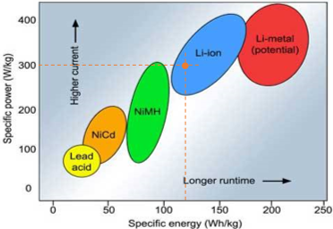

Simscape Electrical provides two pre-configured options for modeling batteries. A first principles based [Battery](matlab:web(fullfile(docroot, 'physmod/sps/ref/battery.html'))) block that uses a behavioral approach and a [Table-based Battery](matlab:web(fullfile(docroot, 'physmod/sps/ref/batterytablebased.html'))) block suitable for matching experimental data. Both of these blocks include the ability to add thermal characteristics and other effects to the model if needed.

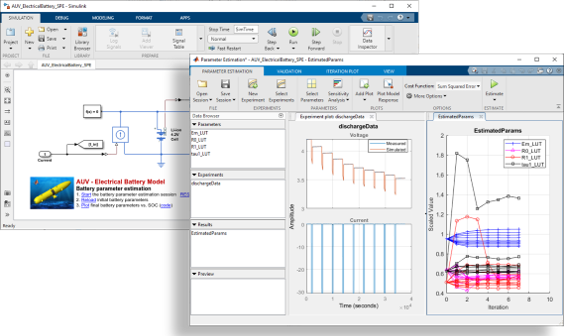

The [Parameter Estimation](matlab:web(fullfile(docroot, 'sldo/parameter-estimation.html'))) App allows us to set up and run a multi-variable optimization to estimate the parameters in a Simulink model using measured data. In our example, we will use this tool to adjust the battery parameters such that the component model matches the discharge curve obtained from an experiment. For a more detailed example of extracting battery parameters from data, including tests for multiple operating temperatures, refer to [this](matlab:web(fullfile(docroot, 'physmod/sps/examples/battery-parameter-extraction-from-data.html'))) documentation page.

open_system('AUV_ElectricalBattery_SPE');

`Copyright 2020 The MathWorks, Inc.`

*Prev: Main Menu*